clc; clear; close all;

## (a) (10%) Use the relation as we have done for a two-node linear element to derive the shape functions for a three-node quadratic element illustrated below where node 2 is in the middle point of the element. 

syms x x1 x2 x3 Ae Ee L b1 b3

p(x) = [1 x x^2];

Me = [
  1 x1 x1^2; ...
  1 x2 x2^2; ...
  1 x3 x3^2; ...
];

Ne(x) = simplify(p(x) / Me)

$$Ne(x) = \left(\begin{array}{ccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)}{\left(x_{1}-x_{3}\right)\,\left(x_{2}-x_{3}\right)} \end{array}\right)$$

## (b) (10%) Plot the values of shape functions vs. x. using MATLAB. 

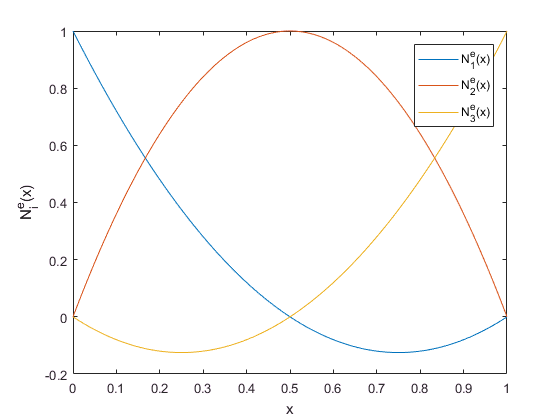

Ne_subs(x) = subs(Ne(x), [x1 x2 x3], [0, 1/2, 1]);

t = 0 : 0.001 : 1;

Ne_cell = Ne_subs(t);

plot(t, Ne_cell{1}, t, Ne_cell{2}, t, Ne_cell{3});
legend('N_{1}^{e}(x)','N_{2}^{e}(x)','N_{3}^{e}(x)');
xlabel('x');
ylabel('N_{i}^{e}(x)');

## (c) (20%) Derive the element stiffness matrix for the element with a constant cross-sectional area and Young’s modulus .

Be = simplify(diff(Ne, x));
simplify(subs(Be, [x2 - x1, x3 - x2, x3 - x1], [1/2*L, 1/2*L, L]))

$$ans(x) = \left(\begin{array}{ccc} -\frac{2\,\left(x_{2}-2\,x+x_{3}\right)}{L^{2}} & \frac{4\,\left(x_{1}-2\,x+x_{3}\right)}{L^{2}} & -\frac{2\,\left(x_{1}-2\,x+x_{2}\right)}{L^{2}} \end{array}\right)$$

Ke = simplify(int(Be.' * Ae * Ee * Be, x, x1, x3));
simplify(subs(Ke, [x1 x2 x3], [0 1/2*L, L]))

$$ans = \begin{array}{l} \left(\begin{array}{ccc} \frac{7\,\mathrm{Ae}\,\mathrm{Ee}}{3\,L} & \sigma_{1} & \frac{\mathrm{Ae}\,\mathrm{Ee}}{3\,L}\\ \sigma_{1} & \frac{16\,\mathrm{Ae}\,\mathrm{Ee}}{3\,L} & \sigma_{1}\\ \frac{\mathrm{Ae}\,\mathrm{Ee}}{3\,L} & \sigma_{1} & \frac{7\,\mathrm{Ae}\,\mathrm{Ee}}{3\,L} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{8\,\mathrm{Ae}\,\mathrm{Ee}}{3\,L} \end{array}$$

## (d) (10%) Derive the external body force matrix subjected to linear distribution of body forces for the element.

b(x) = [-(x - x3), x - x1] / L * [b1; b3];
fe_omega = simplify(int(Ne.' * b, x, x1, x3));
simplify(subs(fe_omega, [x1 x2 x3], [0 1/2*L 1*L]))

$$ans = \left(\begin{array}{c} \frac{L\,b_{1}}{6}\\ \frac{L\,\left(b_{1}+b_{3}\right)}{3}\\ \frac{L\,b_{3}}{6} \end{array}\right)$$